# Measuring the Center of Buoyancy of Boats

### By: Arnaldo Rodriguez-Gonzalez

This MATLAB live-script is designed to help you quickly calculate the center of buoyancy of two different boat types; one with outrigger floats, one without. Use the checkbox to determine if you would like to put outrigger floats on the boat or not, and use the slider to tilt the orientation of the boat in the "ocean". 

The figure below will show a frontal cross-section of the boat, with a red star indicating the center of mass of the boat, and a blue cross indicates the center of buoyancy. The plot will update when moving the slider or checking/unchecking the box. 

The simulation assumes the density of the boat is the same everywhere; therefore, the simulation is scale-free, and you may consider whatever length unit you like for the boat dimensions. Make sure you hit Run (the green arrow above) before changing the tilt angle, or you may get an error!

clear
outrcheck = true;
hull = polyshape([-0.5, -0.5, 0, 0.5, 0.5],[0.5,0,-0.5,0,0.5]);
if outrcheck == 1
    log1 = polyshape([-1.25,-1.25,-1,-1],[0.25,0,0,0.25]);
    log2 = polyshape([1.25,1.25,1,1],[0.25,0,0,0.25]);
    boat = union([hull,log1,log2]);
else
    boat = hull;
end
sea = polyshape([-5,5,5,-5],[0,0,-10,-10]);

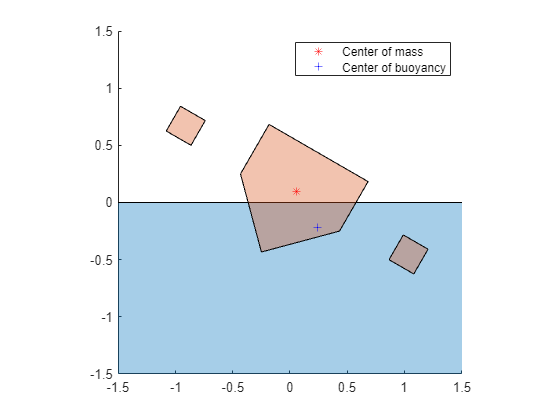

close all
theta =-30;
rotboat = rotate(boat,theta);
h = plot([sea,rotboat]);
hold on
axis equal
xlim([-1.5,1.5])
ylim([-1.5,1.5])
[comx,comy] = centroid(rotboat);
subboat = intersect(rotboat,sea);
[cogx,cogy] = centroid(subboat);
p = plot(comx,comy,'r*',cogx,cogy,'b+');
legend([p(1) p(2)],'Center of mass', 'Center of buoyancy')

## Activities:

- For both the outrigger and no-outrigger case, plot the vertical and horizontal position of the center of mass and the center of buoyancy as a function of angle. What key differences do you see between the outrigger and no-outrigger case?

- Use the information from Problem 1 to calculate the distance between the center of buoyancy and the center of mass. Using this info, plot the "lever arm" associated with the buoyancy force as a function of angle, for both the outrigger and no-outrigger case. Comment on what you see.

- Would the outrigger stabilization mechanism work if there was only one outrigger float? Why, or why not?

- As an engineer, would you design the outrigger floats on this boat to be submerged when the boat is upright? Why, or why not? (Be specific about the pros and cons of each scenario, and look beyond just the buoyancy effects.)